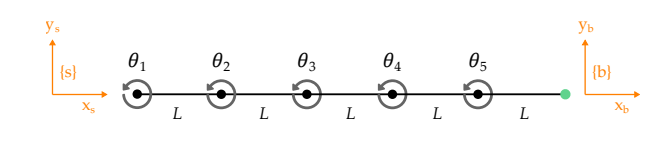

We are building a snake robot. This snake robot moves in a plane and has 5 joints, making it a redundant robot. We are goint to use this redundancy to mimic the motion of real snakes.

We are implementing the numerical inverse kinematics algorithm below. 

Leave $b=0$ within the Jacobian pseudoinverse. Thus, using our code, we will find the inverse kinematics solutions when: 

- **CASE 1: **$L=1$ and the desired end-effector pose is:

                
$$T_{\mathrm{sb}} =\left\lbrack \begin{array}{cccc}
0\ldotp 7071 & -0\ldotp 7071 & 0 & 3\\
0\ldotp 7071 & 0\ldotp 7071 & 0 & 2\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


 We set the initial joint position and write the screws for each joint. Here I include the home transformation matrix to the end of each link, which will be useful for plotting.

Then we set the desired transformation matrix and get the initial end-effector pose. The function **r2axisangle** is included in the support functions folder for numerical inverse kinematics, or in the .m files themselves.

**FINAL JOINT POSITIONS RESULTS ARE CONCLUDED AT THE END OF CASE 3 DEMONSTRATION**

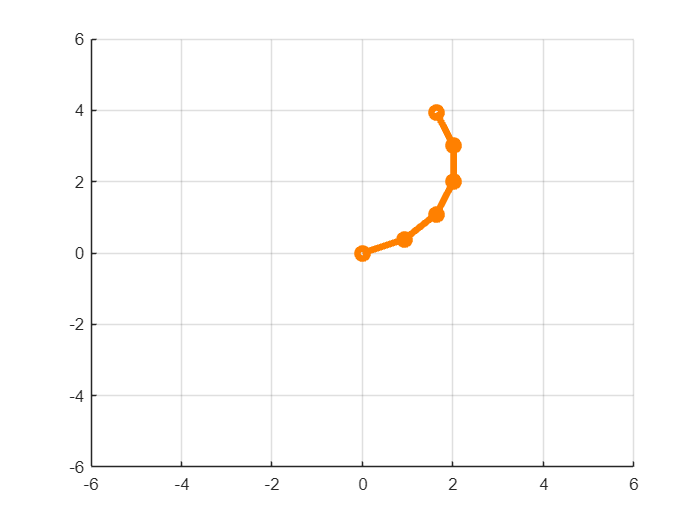

close all
clear
clc

% create figure
figure
axis([-6, 6, -6, 6])
grid on
hold on

% save as a video file
v = VideoWriter('Case_1.mp4', 'MPEG-4');
v.FrameRate = 25;
open(v);

%initial joint values
L = 1;
theta = [pi/8; pi/8; pi/8; pi/8; pi/8];

omega = [0;0;1];

S1 = [0 0 1 0 0 0]';
S2 = [0 0 1 0 -1*L 0]';
S3 = [0 0 1 0 -2*L 0]';
S4 = [0 0 1 0 -3*L 0]';
S5 = [0 0 1 0 -4*L 0]';

S_eq = [S1, S2, S3, S4, S5];   
M = [eye(3), [5*L;0;0]; 0 0 0 1];
M1 = [eye(3), [1*L;0;0]; 0 0 0 1];
M2 = [eye(3), [2*L;0;0]; 0 0 0 1];
M3 = [eye(3), [3*L;0;0]; 0 0 0 1];
M4 = [eye(3), [4*L;0;0]; 0 0 0 1];

% Given desired Transformation matrices T_d
T_d = [rotz(pi/4), [3;2;0]; 0 0 0 1];
Xd = [r2axisangle(T_d(1:3, 1:3)); T_d(1:3,4)];

% T with initial joint positions
T = fk(M, S_eq, theta);
X = [r2axisangle(T(1:3, 1:3)); T(1:3,4)];

while norm(Xd - X) > 1e-2
% plot the robot
% 1. get the position of each link
    p0 = [0; 0];
    T1 = fk(M1, S1, theta(1));
    T2 = fk(M2, [S1, S2], [theta(1), theta(2)]);
    T3 = fk(M3, [S1, S2, S3], [theta(1), theta(2), theta(3)]);
    T4 = fk(M4, [S1, S2, S3, S4], [theta(1), theta(2), theta(3), theta(4)]);
    P_v = [p0, T1(1:2, 4), T2(1:2, 4), T3(1:2, 4), T4(1:2, 4), T(1:2, 4)];

% 2. draw the robot and save the frame

    cla;
    plot(P_v(1,:), P_v(2,:), 'o-', 'color',[1, 0.5, 0],'linewidth',4)
    drawnow
    frame = getframe(gcf);
    writeVideo(v, frame);

% My code Implementation
    JS = JacS(S_eq, theta); % Updating Space Jacobian
    Jb = adjointM(inv(T))*JS; % Updating Body Jacobian
    J_geometric = [T(1:3, 1:3) zeros(3); zeros(3) T(1:3, 1:3)] * Jb; % Updated Geometric Jacobian
    V = Xd - X;

    % Here, we set b vector as the following: b = [-theta(1);0;0;0;0]
    delta_theta = pinv(J_geometric)*V;

    % +(eye(5) - pinv(J_geometric)*J_geometric)*[0;0;0;0;0];
    
    % Updating theta until the while loop is satisfied to get the desired inverse kinematics (joint positions), thus simulating the robot
    theta = double(theta + 0.1 * delta_theta);
    T = fk(M, S_eq, theta);
    X = [r2axisangle(T(1:3, 1:3)); T(1:3,4)];

end


close(v);
close all

 Main loo:. At each iteration, we first plot the robot and save a video frame. Then we calculate the Jacobian and perform numerical inverse kinematics. The loop terminates when the actual pose is close to the desired pose.